# **Control usando estimación de estados**

En el sistema físico de la figura, la corriente a través de las bobinas induce una fuerza magnética que puede equilibrar la fuerza de la gravedad y hacer que la pelota (que está hecha de un material magnético) quede suspendida en el aire. 

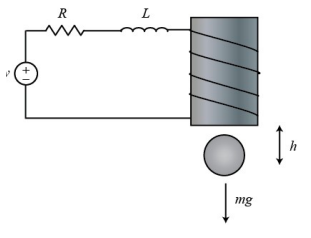

Las ecuaciones del sistema están dadas por: 

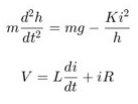

donde h es la posición vertical de la pelota, i es la corriente a través del electroimán, V es el voltaje aplicado, m es la masa de la pelota, g es la aceleración de la gravedad, L es la inductancia, R es la resistencia y K es un coeficiente que determina la fuerza magnética ejercida sobre la pelota. Para simplificar, elegiremos valores m = 0.05 kg, K = 0.0001, L = 0.01 H, R = 1 Ohm, g = 9.81 m/s^2. El sistema está en equilibrio (la pelota está suspendida en el aire) siempre que h = K i^2/mg (en cuyo punto dh/dt = 0). Linealizamos las ecuaciones sobre el punto h = 0,01 m (donde la corriente nominal es de unos 7 amperios) y obtenemos las ecuaciones lineales de espacio de estado:

donde u es la desviación del voltaje de entrada de su valor de equilibrio (ΔV), e y (la salida) es la desviación del voltaje altura de la pelota desde su posición de equilibrio (Δh).

El sistema está parcialmente definido por las matrices:

A = [ 0 1 0; 980 0 -2.8,0 0 -100 ]; 

B = [ 0 0 100 ];

**1)** Defina la matriz C.

close all; clear all; clc;
% Parámetros del sistema.
m = 0.05;
K = 0.0001;
L = 0.01;
R = 1;
g = 9.81;
% Matrices del sistema.
A = [0   1  0;
     980 0 -2.8;
     0   0 -100];
B = [0;0;100];
C = [1 0 0];
D = 0;
I = eye(3);

**2)** Se determina que los polos dominantes a lazo cerrado del sistema deben ser 

p1 = - 20 + 20i 

p2 = - 20 - 20i 

Determine el valor de K y kr. Utilice el método de Ackerman.

Colocamos el tercer polo alejado de los otros dos de modo que no interfiera en la respuesta del sistema, en este caso en $p=-100\;\mathrm{rad}/s$.

syms s % Variable compleja.
polo1 = -20 + 20i;
polo2 = -20 - 20i;
polo3 = -50;
disp('El polinomio deseado del sistema es:')

El polinomio deseado del sistema es:


p_deseado = expand((s - polo1)*(s - polo2)*(s - polo3)) % Polinomio deseado.

$$p\_deseado = s^{3}+90\,s^{2}+2800\,s+40000$$

coef_deseado = coeffs(p_deseado, s); % Coeficientes simbólicos del polinomio anterior.
coef_deseado_double = double(coef_deseado); % Coeficientes en formato double.
Ha = tf([1],[coef_deseado_double(1,4) coef_deseado_double(1,3) coef_deseado_double(1,2) coef_deseado_double(1,1)]); % Función de transferencia.
disp('Los polos del polinomio deseado son:')

Los polos del polinomio deseado son:


disp(pole(Ha))

 -50.0000 + 0.0000i
 -20.0000 +20.0000i
 -20.0000 -20.0000i



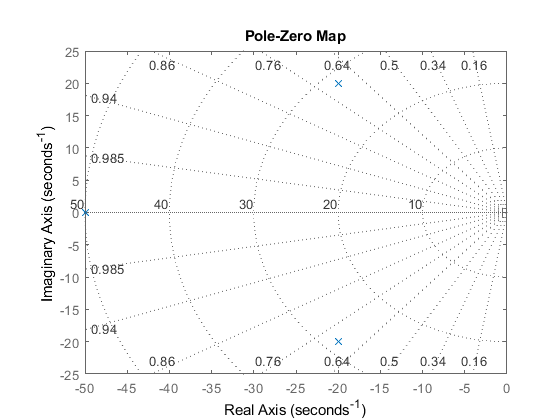

pzmap(Ha) % Graficamos los polos y ceros en el plano de Laplace.
grid on


% Coeficientes del polinomio deseado.
p3 = coef_deseado_double(1,1);
p2 = coef_deseado_double(1,2);
p1 = coef_deseado_double(1,3);

disp('Polinomio característico:')

Polinomio característico:


p_caracteristico = det(s*I-A)

$$p\_caracteristico = s^{3}+100\,s^{2}-980\,s-98000$$

coef_caracteristico = coeffs(p_caracteristico,s); % Obtenemos los coeficientes simbólicos del polinomio característico.
coef_caracteristico_double = double(coef_caracteristico); % Coeficientes formato double.

% Coeficientes del polinomio característico.
a3 = coef_caracteristico_double(1,1);
a2 = coef_caracteristico_double(1,2);
a1 = coef_caracteristico_double(1,3);

% Formula de Ackermann.
Wr = [B A*B A^2*B]; % Matriz de alcanzabilidad.
Wr_tilde = inv([1 a1 a2;
                0 1  a1;
                0 0  1]);
K = [p1-a1 p2-a2 p3-a3]*Wr_tilde*inv(Wr)

K =  -457.8571  -13.5000   -0.1000



% Determinación de kr.
kr = -1/(C*inv(A-B*K)*B)

kr = -142.8571

% Corroboramos.
Kprima = acker(A,B,[polo1 polo2 polo3])

Kprima =  -457.8571  -13.5000   -0.1000



sys = ss(A,B,C,D);
krprima = rscale(sys,K)

krprima = -142.8571

**3)** Mida el valor del sobrepico y el tiempo de establecimiento de y.

ha = stepplot(Ha) % Respuesta al escalón unitario.


ha =

	resppack.timeplot



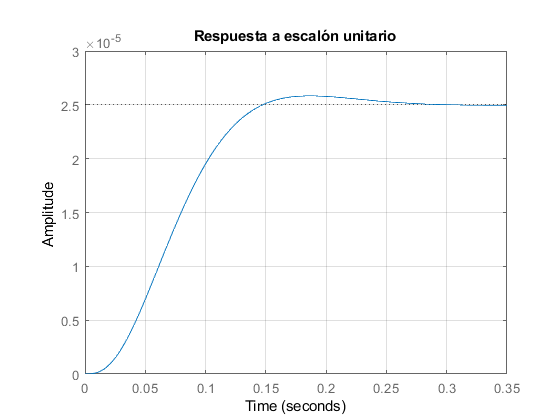

setoptions(ha,'Grid','on');
title('Respuesta a escalón unitario')

sa = stepinfo(Ha) % Comprobamos las especificaciones de diseño del sistema.

sa = struct with fields:
        RiseTime: 0.0877
    SettlingTime: 0.2291
     SettlingMin: 2.2626e-05
     SettlingMax: 2.5831e-05
       Overshoot: 3.3227
      Undershoot: 0
            Peak: 2.5831e-05
        PeakTime: 0.1860


**4)** Desarrolle un observador para este sistema. Cierre el bucle de realimentación a través del observador.

% Establecemos los polos del observador como 5 veces más rapidos que el
% polo más rápido del sistema a lazo cerrado.
disp('Situamos los polos del observador en lazo cerrado en:')

Situamos los polos del observador en lazo cerrado en:


polo = polo3*5

polo = -250

disp('Polinomio deseado del observador a lazo cerrado:')

Polinomio deseado del observador a lazo cerrado:


p_deseado = expand((s - polo)^3) % Polinomio deseado.

$$p\_deseado = s^{3}+750\,s^{2}+187500\,s+15625000$$

coef_obs_deseado = coeffs(p_deseado, s); % Coeficientes del polinomio deseado.
coef_obs_deseado_double = double(coef_obs_deseado); % Coeficientes en formato double.

syms l1 l2 l3
L = [l1 l2 l3]'; % Matriz de ganancia del obsv. a lazo cerrado.
p_observador = simplify(det(s*I - A + L*C))

$$p\_observador = 100\,\bar{l_{2}}-980\,s-\frac{14\,\bar{l_{3}}}{5}+s^{2}\,\bar{l_{1}}+100\,s\,\bar{l_{1}}+s\,\bar{l_{2}}+100\,s^{2}+s^{3}-98000$$

coef_obs = coeffs(p_observador, s) % Coeficientes del polinomio del observador.

$$coef\_obs = \left(\begin{array}{cccc} 100\,\bar{l_{2}}-\frac{14\,\bar{l_{3}}}{5}-98000 & 100\,\bar{l_{1}}+\bar{l_{2}}-980 & \bar{l_{1}}+100 & 1 \end{array}\right)$$


% Igualamos los coeficientes.
eqns = [coef_obs == coef_obs_deseado_double];

% Resolvemos las ecuaciones.
sol = solve(eqns, [l1, l2, l3]);

% Mostramos los coeficientes resultantes.
disp("Las ganancias del observador son:");

Las ganancias del observador son:


l1_double = double(sol.l1);
l2_double = double(sol.l2);
l3_double = double(sol.l3);
disp('l1:')

l1:


disp(l1_double);

   650



disp('l2:')

l2:


disp(l2_double);

      123480



disp('l3:')

l3:


disp(l3_double);

  -1.2054e+06



L = [l1_double l2_double l3_double]';

% Corroboramos las ganancias del observador:
polos_deseados_observdaor = eig(A - L*C)

polos_deseados_observdaor = 	1.0e+02 *

  -2.5000 + 0.0000i
  -2.5000 - 0.0000i
  -2.5000 + 0.0000i



% Debido a la dualidad entre la observabilidad y la controlabilidad, 
% podemos utilizar las misma tecnica utilizada para encontrar la matriz K (Ackermann) 
% reemplazando la matriz B por la matriz C tomando las traspuestas de cada matriz:

Lprima = acker(A',C',[polo polo polo])'

Lprima = 	1.0e+06 *

    0.0006
    0.1235
   -1.2054


**5)** Grafique las variables de interés del sistema.

Es común escribir las ecuaciones combinadas tanto del sistema como del observador a a partir de agregar a las ecuaciones de espacio de estado del sistema el error de estimación dado por $e=x-\tilde{x}$. Utilizamos el estado estimado para la realimentación. Podemos representar entonces las matrices que modelan este sistema completo como.

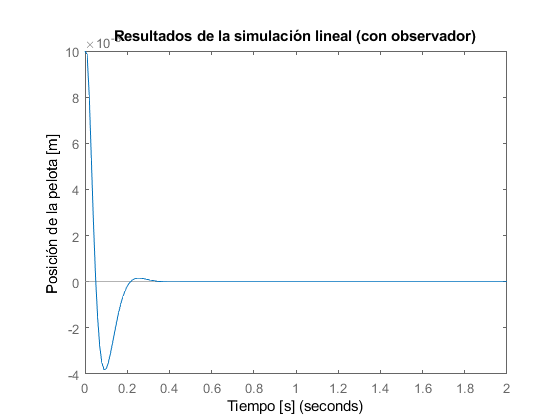

At = [ A-B*K             B*K
       zeros(size(A))    A-L*C ];

Bt = [    B*kr
       zeros(size(B)) ];

Ct = [ C    zeros(size(C)) ];

% Respuesta de todas las variables internas.
t = 0:0.01:2;
u = zeros(size(t));
x0 = [0.01 0 0];
sys = ss(At,Bt,Ct,0);
lsim(sys,u,t,[x0 x0]);

title('Resultados de la simulación lineal (con observador)')
xlabel('Tiempo [s]')
ylabel('Posición de la pelota [m]')

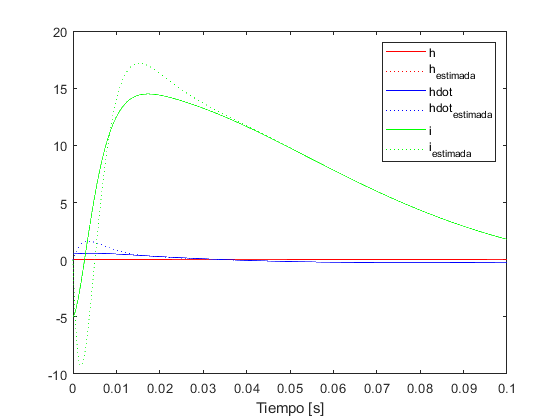


% Respuesta de cada una de las variables internas, tanto del sistema como
% del observador. La función lsim devuelve x y e, debemos hacer x - e para
% conocer x_tilde.

t = 0:1E-6:0.1;
u = zeros(size(t));
x0 = [0.01 0.5 -5]; % Otro estado incial.
[y,t,x_total] = lsim(sys,u,t,[x0 x0]);

n = 3; % Orden del sistema.
x = x_total(:,1:n); % Variables de estado del sistema.
e = x_total(:,n+1:end); % Estado.
x_tilde = x - e; % Variables de estado estimadas.

% Guardamos las variables de estado en vectores.
h = x(:,1); 
h_dot = x(:,2); 
i = x(:,3);
h_tilde = x_tilde(:,1); 
h_dot_tilde = x_tilde(:,2); 
i_tilde = x_tilde(:,3);

% Ploteamos todo.
plot(t,h,'-r',t,h_tilde,':r',t,h_dot,'-b',t,h_dot_tilde,':b',t,i,'-g',t,i_tilde,':g')
legend('h','h_{estimada}','hdot','hdot_{estimada}','i','i_{estimada}')
xlabel('Tiempo [s]')

Se observa un transitorio  de diferencias entre las variables del sistema y las estimadas, luego las variables estimadas convergen a las del sistema con lo cual el observador ha sido planteado adecuadamente.